# Project - Stellar Motion

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data and defines measurement parameters.

load starData
nObs = size(spectra,1)

nObs = 357

lambdaStart = 630.02

lambdaStart = 630.0200

lambdaDelta = 0.14

lambdaDelta = 0.1400

## Task 1

lambdaEnd = lambdaStart + (nObs-1)*lambdaDelta

lambdaEnd = 679.8600

% lambda = (lambdaStart:lambdaDelta:lambdaEnd)
lambda = [];
tmp = lambdaStart;
while tmp <= lambdaEnd
    % lambda = [lambda,tmp];
    lambda(end+1) = tmp;
    tmp = tmp + lambdaDelta;
end
lambda

lambda =   630.0200  630.1600  630.3000  630.4400  630.5800  630.7200  630.8600  631.0000  631.1400  631.2800  631.4200  631.5600  631.7000  631.8400  631.9800  632.1200  632.2600  632.4000  632.5400  632.6800  632.8200  632.9600  633.1000  633.2400  633.3800  633.5200  633.6600  633.8000  633.9400  634.0800  634.2200  634.3600  634.5000  634.6400  634.7800  634.9200  635.0600  635.2000  635.3400  635.4800  635.6200  635.7600  635.9000  636.0400  636.1800  636.3200  636.4600  636.6000  636.7400  636.8800


## Task 2 & 7

% ---2---
% s = spectra(1:end,6)
% s = spectra(:,6)
% ---7---
% s = spectra(:,2)
% ---after---
% size(spectra)
s = spectra(:,7)

s = 1.0e-13 *

    0.3918
    0.3821
    0.3712
    0.3776
    0.3910
    0.3955
    0.4023
    0.3986
    0.3874
    0.3793


## Task 3

plot(lambda,s,".-")
xlabel("Wavelength")
ylabel("Intensity")

## Task 4

[sHa,idx] = min(s)

sHa = 2.2140e-14

idx = 185

lambdaHa = lambda(idx)

lambdaHa = 655.7800

## Task 5

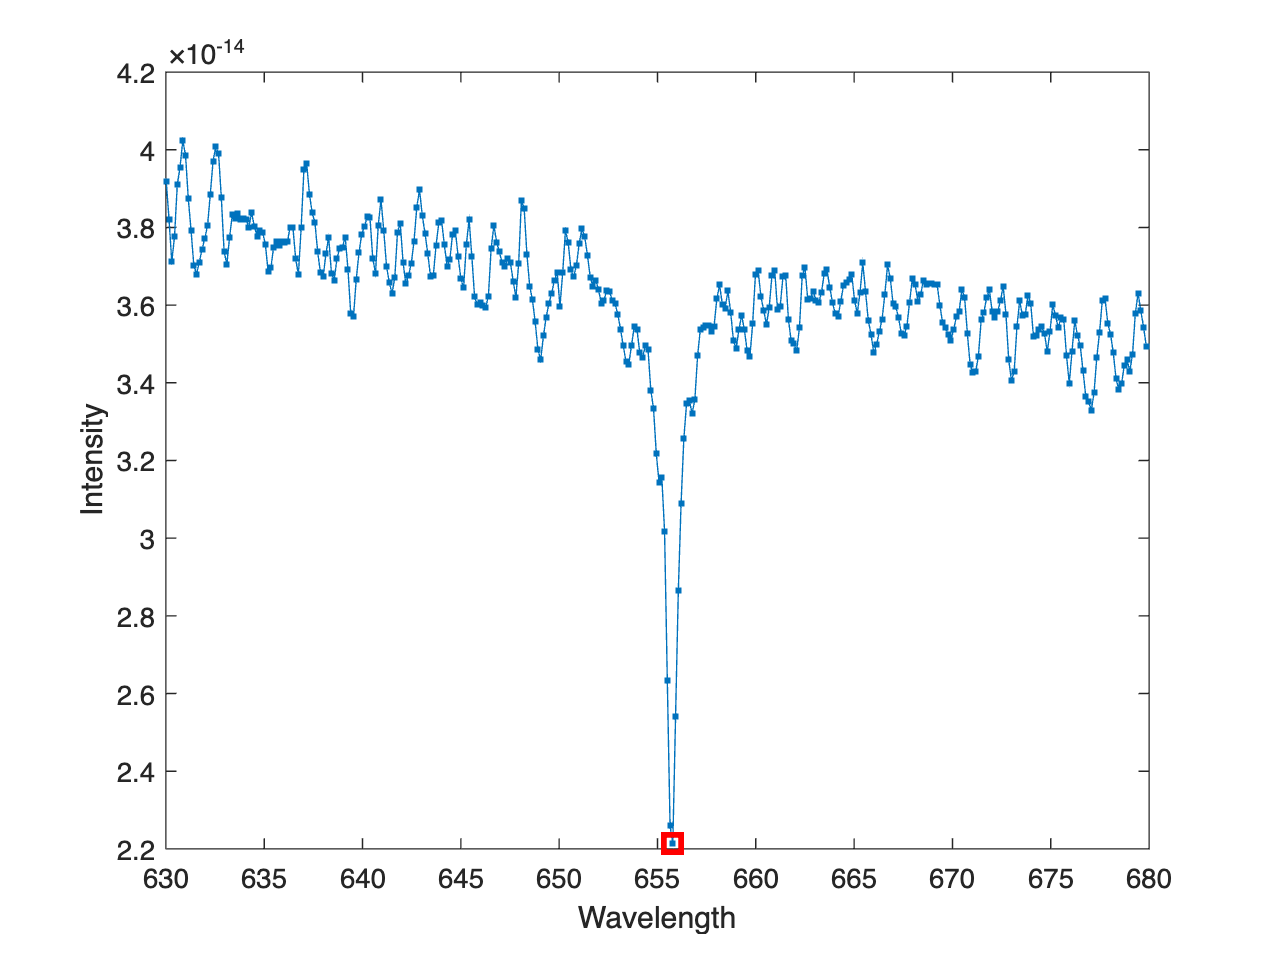

hold on
plot(lambdaHa,sHa,"rs",MarkerSize=8,LineWidth=3)
hold off

## Task 6

sol = 299792.458; % in km/s
% redShift = lambda(idx-1) or lambdaHa
redShift = 656.28; % redShift corrected, and given
z = (lambdaHa/redShift)-1

z = -7.6187e-04

speed = z * sol

speed = -228.4029

## Further Practice